# **Εργασία στην Ψηφιακή Επεξεργασία Σήματος**

## **Χατζησάββας Χρήστος **

# **Ερώτημα α)**

Αρχικά ξεκινάω για **p = 10**:

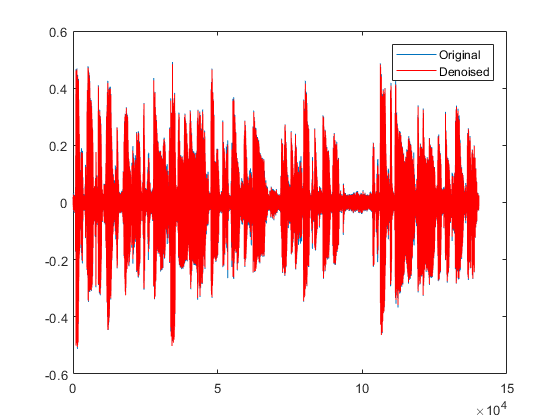

clc;clear
[s_temp,Fs] = audioread('guit1.wav');
s = s_temp';
s_size = size(s,2);
noise = 0.01*randn(1,s_size);
x = s + noise;
rxx = xcorr(x);
rxd = xcorr(x,s);
rxx = rxx(s_size:s_size + 9);
rxd = rxd(s_size:s_size + 9);
Rxx = toeplitz(rxx);
w = Rxx\rxd';
z = filter(w,1,x);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z-s).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.414 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 19.7053 dB


Συνεχίζω με **p = 20**:

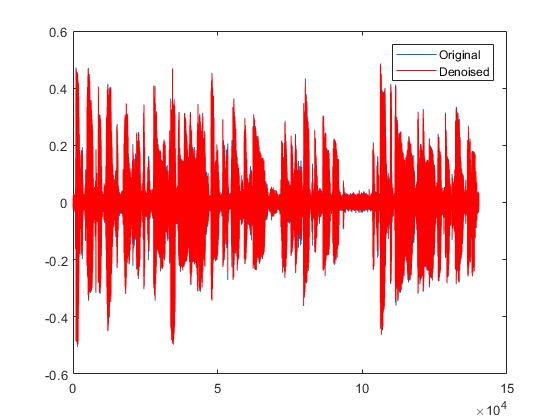

clc;clear
[s_temp,Fs] = audioread('guit1.wav');
s = s_temp';
s_size = size(s,2);
noise = 0.01*randn(1,s_size);
x = s + noise;
rxx = xcorr(x);
rxd = xcorr(x,s);
rxx = rxx(s_size:s_size + 19);
rxd = rxd(s_size:s_size + 19);
Rxx = toeplitz(rxx);
w = Rxx\rxd';
z = filter(w,1,x);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z-s).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.4297 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 19.7216 dB


Συνεχίζω με **p = 30**:

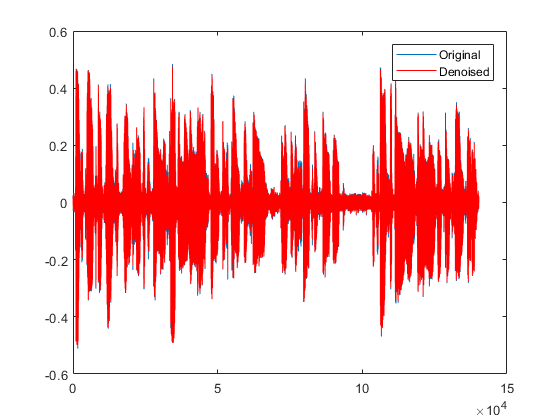

clc;clear
[s_temp,Fs] = audioread('guit1.wav');
s = s_temp';
s_size = size(s,2);
noise = 0.01*randn(1,s_size);
x = s + noise;
rxx = xcorr(x);
rxd = xcorr(x,s);
rxx = rxx(s_size:s_size + 29);
rxd = rxd(s_size:s_size + 29);
Rxx = toeplitz(rxx);
w = Rxx\rxd';
z = filter(w,1,x);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z-s).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.4437 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 19.7437 dB


Στο συγκεκριμένο ερώτημα παρατηρούμε ότι για όλες τις τάξεις φίλτρου που δοκιμάσαμε ο θόρυβος παραμένει στην έξοδο, πράγμα που ακούγεται αλλά και μπορεί να παρατηρηθεί στα plot.Παρόλα αυτά παρατηρούμε μια πολύ μικρή αύξηση στο SNR σε κάθε περίπτωση.

# Ερώτημα β)

Για** p=10:**

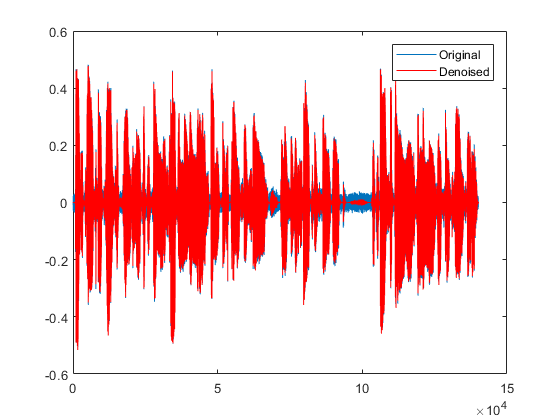

clc;clear
[s,Fs] = audioread('guit1.wav');
s_size = size(s,1);
S = frame_wind (s, 256, 0.5);
s_out = frame_recon(S,0.5);

noise = 0.01*randn(1,s_size);
x = s + noise';
X = frame_wind (x, 256, 0.5);
X_size2 = size(X,2);
X_size1 = size(X,1);
Z = zeros(256,1095);

x = frame_recon(X,0.5);

for i = 1:X_size2
    rxx = xcorr(X(:,i));
    rxd = xcorr(X(:,i),S(:,i));
    rxx = rxx(X_size1:X_size1+9); 
    rxd = rxd(X_size1:X_size1+9);
    Rxx = toeplitz(rxx);
    w = pinv(Rxx,0.0001)*rxd;
    z = filter(w,1,X(:,i));
    Z(:,i) = z;
end

z = frame_recon(Z,0.5);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z-s_out).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.4 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 21.4031 dB


Τρέχω για **p=20:**

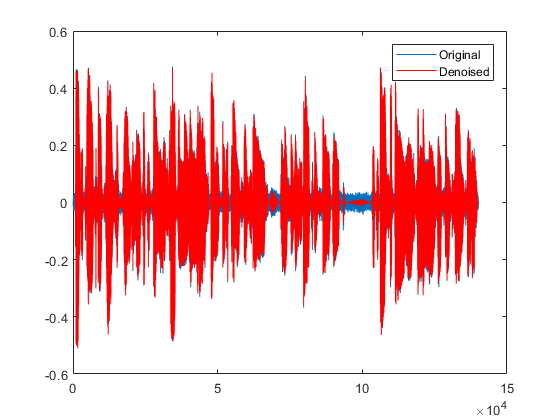

clc;clear
[s,Fs] = audioread('guit1.wav');
s_size = size(s,1);
S = frame_wind (s, 256, 0.5);
s_out = frame_recon(S,0.5);

noise = 0.01*randn(1,s_size);
x = s + noise';
X = frame_wind (x, 256, 0.5);
X_size2 = size(X,2);
X_size1 = size(X,1);
Z = zeros(256,1095);

x = frame_recon(X,0.5);

for i = 1:X_size2
    rxx = xcorr(X(:,i));
    rxd = xcorr(X(:,i),S(:,i));
    rxx = rxx(X_size1:X_size1+19); 
    rxd = rxd(X_size1:X_size1+19);
    Rxx = toeplitz(rxx);
    w = pinv(Rxx,0.0001)*rxd;
    z = filter(w,1,X(:,i));
    Z(:,i) = z;
end

z = frame_recon(Z,0.5);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z - s_out).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.3669 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 21.4767 dB


Τρέχω για **p=30:**

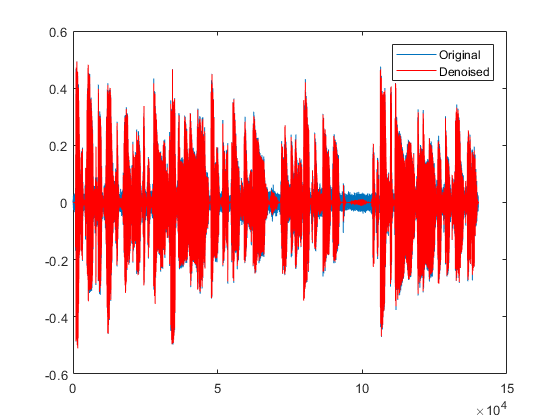

clc;clear
[s,Fs] = audioread('guit1.wav');
s_size = size(s,1);
S = frame_wind (s, 256, 0.5);
s_out = frame_recon(S,0.5);

noise = 0.01*randn(1,s_size);
x = s + noise';
X = frame_wind (x, 256, 0.5);
X_size2 = size(X,2);
X_size1 = size(X,1);
Z = zeros(256,1095);

x = frame_recon(X,0.5);

for i = 1:X_size2
    rxx = xcorr(X(:,i));
    rxd = xcorr(X(:,i),S(:,i));
    rxx = rxx(X_size1:X_size1+29); 
    rxd = rxd(X_size1:X_size1+29);
    Rxx = toeplitz(rxx);
    w = pinv(Rxx,0.0001)*rxd;
    z = filter(w,1,X(:,i));
    Z(:,i) = z;
end

z = frame_recon(Z,0.5);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z - s_out).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.3643 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 21.4254 dB


Στο συγκεκριμένο ερώτημα παρατηρούμε ότι για όλες τις τάξεις φίλτρου που δοκιμάσαμε ο θόρυβος φαίνεται να εξαλείφεται ικανοποιητικά στην έξοδο, πράγμα που γίνεται ιδιαίτερα αντιληπτό εάν ακούσουμε με soundsc το αρχικό σήμα και την έξοδο. Ωστόσο υπάρχει ένα μικρό αποτύπωμα θορύβου ιδιαίτερα όταν μιλάει ο ομιλητής. Στο SNR όπως αναμένουμε οι τιμές του αποθορυβοποιημένου σήματος είναι μεγαλύτερες από αυτές του ενθόρυβου σήματος.

# Ερώτημα γ)

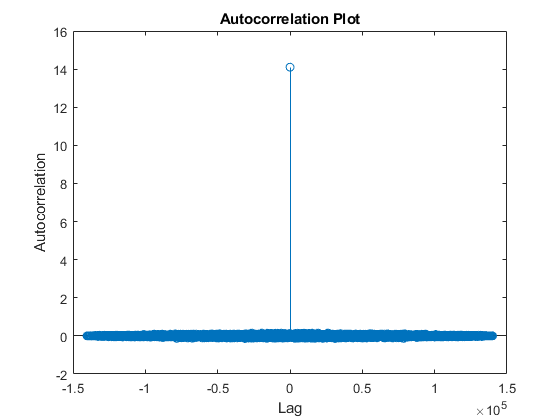

clc;clear
[s_temp,~] = audioread('guit1.wav');
s = s_temp';
s_size = size(s,2);
noise = 0.01*randn(1,s_size);

noise_autocor = xcorr(noise);
lag = -(length(noise)-1):(length(noise)-1);
stem(lag, noise_autocor);
xlabel('Lag');
ylabel('Autocorrelation');
title('Autocorrelation Plot');

Ο θόρυβος προκύπτει να είναι σχεδόν λευκός αφού στην τιμή 0 παρουσιάζει μια υψηλή τιμή ενώ στις υπόλοιπες τιμές του οριζόντιου άξονα είναι κοντά στο 0. Παρατηρείται δηλαδή συνάρτηση παρόμοια με την Δέλτα του Dirac.

# Ερώτημα δ)

Προκειμένου να βρούμε ένα διάστημα που δεν υπάρχει φωνή κάνουμε plot την γραφική του σήματος με τον θόρυβο και κοιτάμε να βρούμε μια περιοχή με χαμηλό πλάτος

**Για p = 10:**

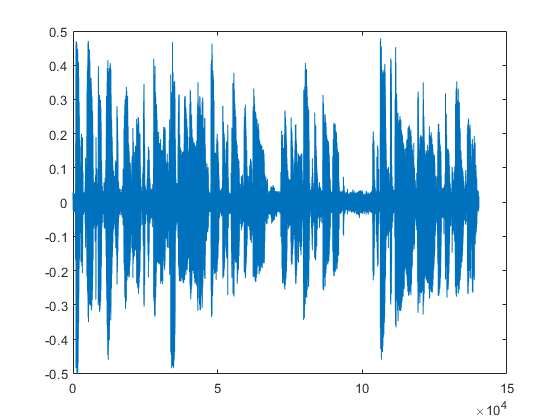

clc;clear
[s_temp,Fs] = audioread('guit1.wav');
s = s_temp';
s_size = size(s,2);
noise = 0.01*randn(1,s_size);
x= s + noise;
plot(x)

Παρατηρούμε κοντά στο 10* 10^4 χαμηλό πλάτος άρα εκεί είναι ο θόρυβος. Βρίσκουμε πιο συγκεκριμένα την περιοχή με την χρήση του data cursor.

start_no_voice = 94700;
stop_no_voice = 102200;
noise_area = x(start_no_voice : stop_no_voice);

Μπορούμε να επιβεβαιώσουμε την ύπαρξη θορύβου κάνοντας soundsc το noise_area.

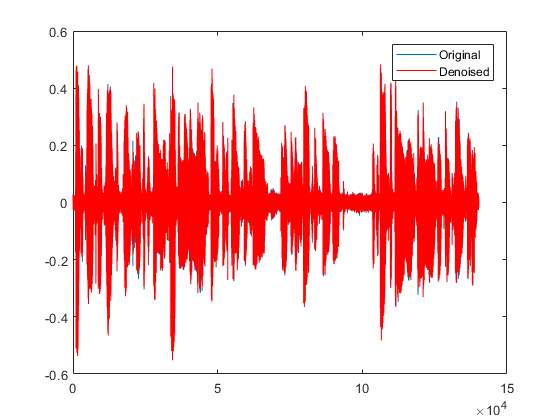

rxx = xcorr(x);
noise_autocor = xcorr(noise_area);
noise_middle = floor(length(noise_autocor) / 2);
x_middle = floor(length(rxx) / 2);
filter_rank = 10;
rnn = noise_autocor(noise_middle:noise_middle + filter_rank - 1);
rxx = rxx(x_middle:x_middle + filter_rank - 1);
rxd = rxx - rnn;
Rxx = toeplitz(rxx);
w = Rxx\rxd';
z = filter(w,1,x);

%soundsc(x,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z-s).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.4366 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 18.7084 dB


**Για p = 20:**

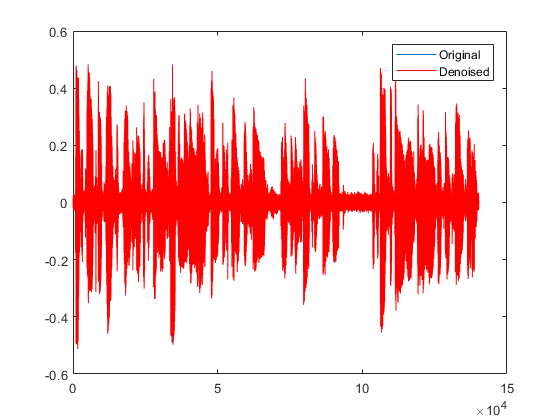

clc;clear
[s_temp,Fs] = audioread('guit1.wav');
s = s_temp';
s_size = size(s,2);
noise = 0.01*randn(1,s_size);
x = s + noise;

%find a space in x signal where only noise appears (plot and observe where
%we have low amplitude)
start_no_voice = 94700;
stop_no_voice = 102200;
noise_area = x(start_no_voice : stop_no_voice);

rxx = xcorr(x);
noise_autocor = xcorr(noise_area);
noise_middle = floor(length(noise_autocor) / 2);
x_middle = floor(length(rxx) / 2);
filter_rank = 20;
rnn = noise_autocor(noise_middle:noise_middle + filter_rank -1);
rxx = rxx(x_middle:x_middle + filter_rank -1);
rxd = rxx - rnn;
Rxx = toeplitz(rxx);
w = Rxx\rxd';
z = filter(w,1,x);

%soundsc(x,Fs)
% Plotting the signals
plot(x);hold on;plot(z, 'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z-s).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.4264 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 19.4033 dB


**Για p = 30:**

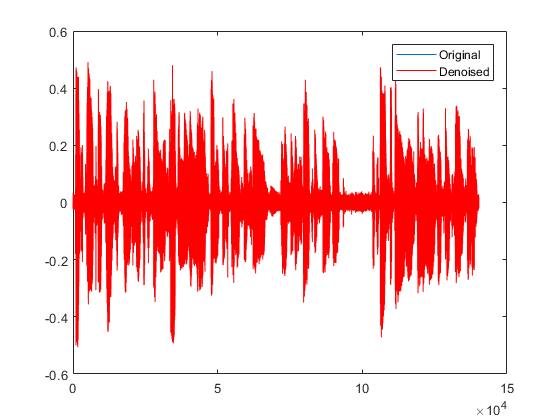

clc;clear
[s_temp,Fs] = audioread('guit1.wav');
s = s_temp';
s_size = size(s,2);
noise = 0.01*randn(1,s_size);
x= s + noise;

%find a space in x signal where only noise appears (plot and observe where
%we have low amplitude)
start_no_voice = 94700;
stop_no_voice = 102200;
noise_area = x(start_no_voice : stop_no_voice);

rxx = xcorr(x);
noise_autocor = xcorr(noise_area);
noise_middle = floor(length(noise_autocor) / 2);
x_middle = floor(length(rxx) / 2);
filter_rank = 30;
rnn = noise_autocor(noise_middle:noise_middle + filter_rank - 1);
rxx = rxx(x_middle:x_middle + filter_rank - 1);
rxd = rxx - rnn;
Rxx = toeplitz(rxx);
w = Rxx\rxd';
z = filter(w,1,x);

%soundsc(x,Fs)
% Plotting the signals
plot(x);hold on;plot(z, 'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z-s).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.4281 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 19.4381 dB


Εδώ όπως και στο ερώτημα α δεν παρατηρούμε αποθορυβοποίηση για καμία από τις τάξεις φίλτρων της άσκησης. Οι τιμές των SNR είναι μικρότερες σε σχέση με του ερωτήματος α που είναι λογικό αφού κάνουμε αποθορυβοποίηση χωρίς να γνωρίζουμε το αρχικό "καθαρό" σήμα.

# Ερώτημα ε)

Προκειμένου να βρούμε αν ένα παράθυρο έχει θόρυβο θα χρησιμοποιήσουμε την μέθοδο με τον υπολογισμό των Ehigh και Elow από την τεχνολογία ήχου. Βρίσκοντας ένα κατόφλι για τον θόρυβο, κρίνουμε εάν ένα παράθυρο έχει θόρυβο ή φωνή.

**Για p = 10:**

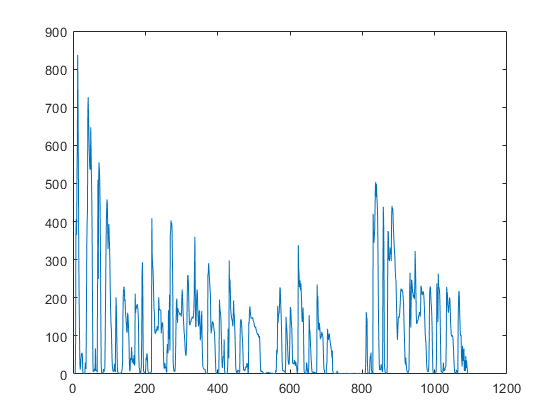

clc;clear
[s,Fs] = audioread('guit1.wav');
s_size = size(s,1);
S = frame_wind (s, 256, 0.5);
s_out = frame_recon(S,0.5);
noise = 0.01*randn(1,s_size);
x = s + noise';
X = frame_wind (x, 256, 0.5);
X_size2 = size(X,2);
X_size1 = size(X,1);
x = frame_recon(X,0.5);

Z = zeros(256,1095);

XF = fft(X);
frame = 256;
[~, columns] = size(XF);
Elow = zeros(1,columns);
Ehigh = zeros(1,columns);
%Elow Calculation
temp1 = 0; % counter initialization

for k = 1:columns
    for m = 1:(frame/4)
        temp1 = temp1 + (abs(XF(m,k)))^2;
    end
    Elow(1,k) = temp1;
    temp1 = 0;
end

%Ehigh Calculation
temp2 = 0; % counter initialization

for k = 1:columns
    for m = ((frame/4)+1):(frame/2)
        temp2 = temp2 + (abs(XF(m,k)))^2;
    end
    Ehigh(1,k) = temp2;
    temp2 = 0;
end

Etotal = Elow + Ehigh; %total Energy
plot(Etotal)

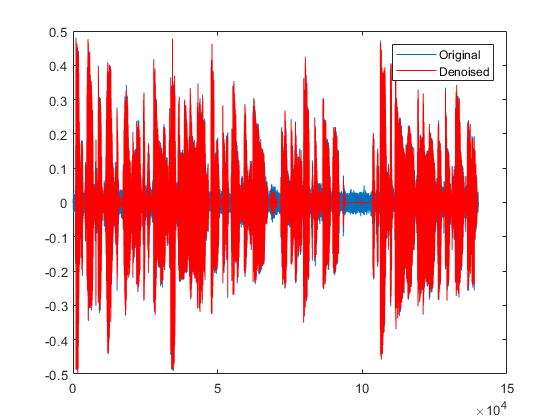

Noisy_window = zeros(1,columns);

%find all windows which have noise
for j = 1:size(Etotal,2)
    if Etotal(1,j) < 2
        Noisy_window(1,j) = 1;
    else
        Noisy_window(1,j) = 0;
    end
end

for i = 1:X_size2
    if Noisy_window(1,i) == 1
        temp1 = i;
    end
    
    rxx = xcorr(X(:,i));
    rnn = xcorr(X(:,temp1));
    rxx = rxx(X_size1:X_size1 + 9);
    rnn = rnn(X_size1:X_size1 + 9);
    rxd = rxx -rnn;
    Rxx = toeplitz(rxx);
    w = pinv(Rxx,0.0001)*rxd;
    z = filter(w,1,X(:,i));
    Z(:,i) = z;
end

z = frame_recon(Z,0.5);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z - s_out).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.3985 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 20.9002 dB


**Για p = 20:**

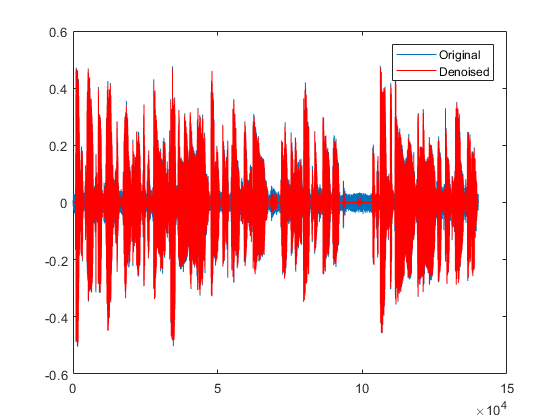

clc;clear
[s,Fs] = audioread('guit1.wav');
s_size = size(s,1);
S = frame_wind (s, 256, 0.5);
s_out = frame_recon(S,0.5);
noise = 0.01*randn(1,s_size);
x = s + noise';
X = frame_wind (x, 256, 0.5);
X_size2 = size(X,2);
X_size1 = size(X,1);
x = frame_recon(X,0.5);

Z = zeros(256,1095);

XF = fft(X);
frame = 256;
[~, columns] = size(XF);

%Elow Calculation
temp1 = 0; % counter initialization

for k = 1:columns
    for m = 1:(frame/4)
        temp1 = temp1 + (abs(XF(m,k)))^2;
    end
    Elow(1,k) = temp1;
    temp1 = 0;
end

%Ehigh Calculation
temp2 = 0; % counter initialization

for k = 1:columns
    for m = ((frame/4)+1):(frame/2)
        temp2 = temp2 + (abs(XF(m,k)))^2;
    end
    Ehigh(1,k) = temp2;
    temp2 = 0;
end

Etotal = Elow + Ehigh; %total Energy
%plot(Etotal)

Noisy_window = zeros(1,size(Etotal,2));

%find all windows which have noise
for j = 1:size(Etotal,2)
    if Etotal(1,j) <2
        Noisy_window(1,j) = 1;
    else
        Noisy_window(1,j) = 0;
    end
end

for i = 1:X_size2
    if Noisy_window(1,i) == 1
        temp1 = i;
    end
    rxx = xcorr(X(:,i));
    rnn = xcorr(X(:,temp1));
    rxx = rxx(X_size1:X_size1 + 19); 
    rnn = rnn(X_size1:X_size1 + 19);
    rxd = rxx - rnn;
    Rxx = toeplitz(rxx);
    w = pinv(Rxx,0.0001)*rxd;
    z = filter(w,1,X(:,i));
    Z(:,i) = z;
end

z = frame_recon(Z,0.5);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z - s_out).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.4051 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 20.453 dB


**Για p = 30:**

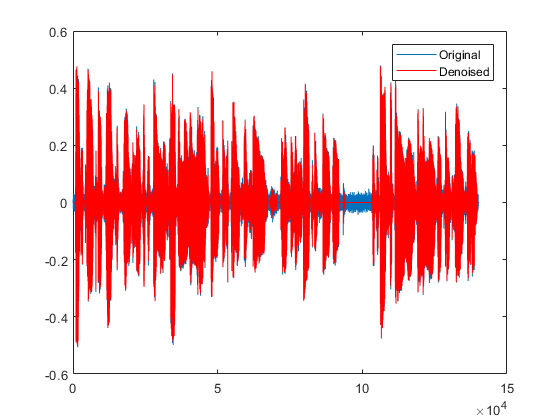

clc;clear
[s,Fs] = audioread('guit1.wav');
s_size = size(s,1);
S = frame_wind (s, 256, 0.5);
s_out = frame_recon(S,0.5);
noise = 0.01*randn(1,s_size);
x = s + noise';
X = frame_wind (x, 256, 0.5);
X_size2 = size(X,2);
X_size1 = size(X,1);
x = frame_recon(X,0.5);

Z = zeros(256,1095);

XF = fft(X);
frame = 256;
[rows, columns] = size(XF);

%Elow Calculation
temp1 = 0; % counter initialization

for k = 1:columns
    for m = 1:(frame/4)
        temp1 = temp1 + (abs(XF(m,k)))^2;
    end
    Elow(1,k) = temp1;
    temp1 = 0;
end

%Ehigh Calculation
temp2 = 0; % counter initialization

for k = 1:columns
    for m = ((frame/4)+1):(frame/2)
        temp2 = temp2 + (abs(XF(m,k)))^2;
    end
    Ehigh(1,k) = temp2;
    temp2 = 0;
end

Etotal = Elow + Ehigh; %total Energy
%plot(Etotal)

Noisy_window = zeros(1,columns);

%find all windows which have noise
for j = 1:size(Etotal,2)
    if Etotal(1,j) < 2
        Noisy_window(1,j) = 1;
    else
        Noisy_window(1,j) = 0;
    end
end

for i = 1:X_size2
    if Noisy_window(1,i) == 1
        temp1 = i;
    end
    
    rxx=xcorr(X(:,i));
    rnn = xcorr(X(:,temp1));
    rxx = rxx(X_size1:X_size1 + 29); 
    rnn = rnn(X_size1:X_size1 + 29);
    rxd = rxx -rnn;
    Rxx = toeplitz(rxx);
    w = pinv(Rxx,0.0001)*rxd;
    z = filter(w,1,X(:,i));
    Z(:,i) = z;
end

z = frame_recon(Z,0.5);


%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Denoised');

SNR_full_noise = 10 * log10(sum(x.^2) / sum(noise.^2));
SNR_with_noise_cancellation = 10 * log10(sum(z.^2) / sum((z - s_out).^2));
disp(['SNR for noisy signal: ' num2str(SNR_full_noise) ' dB']);

SNR for noisy signal: 19.3904 dB


disp(['SNR for filtered signal: ' num2str(SNR_with_noise_cancellation) ' dB']);

SNR for filtered signal: 20.2446 dB


Σε αυτήν την υλοποίηση παρατηρούμε εξάλειψη του θορύβου σε έναν αρκετά καλό βαθμό. Σε σύγκριση με το ερώτημα Β παρατηρούμε τις τιμές του SNR να είναι περίπου κατά 1 dB μικρότερες που είναι λογικό αν λάβουμε υπόψην μας πως στην πραγματικότητα δεν γνωρίζουμε το καθαρό σήμα αλλά προσπαθούμε εμείς να  φιλτράρουμε το θορυβώδες.

# Ερώτημα στ)

Θα προβλέψουμε τις επόμενες 2,10,15 τιμές του σήματος είσοδου αντίστοιχα χρησιμοποιώντας φίλτρο τάξης 20.(αυτό μπορεί εύκολα να αλλάξει τροποποιώντας την παράμετρο filter_grade)

**Για πρόβλεψη 2 θέσεων:**

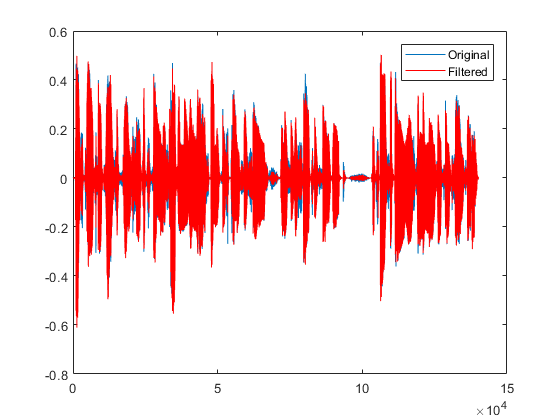

clc;clear
[x,Fs] = audioread('guit1.wav');

X= frame_wind (x, 256, 0.5);
X_size1 = size(X,1);
X_size2 = size(X,2);
x = frame_recon(X,0.5);

Z = zeros(256,1095);
filter_grade = 20; %change the filter grade
prediction_param = 2; %prediction parameter 

for i = 1:X_size2
    rss = xcorr(X(:,i));
    rxx = rss(X_size1:X_size1 + filter_grade - 1); 
    rss = rss((X_size1+ prediction_param):(X_size1 + prediction_param) + filter_grade - 1);
    Rxx = toeplitz(rxx);
    w = pinv(Rxx,0.0001)*rss;
    z = filter(w,1,X(:,i));
    Z(:,i) = z;
end

z = frame_recon(Z,0.5);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Filtered');

SNR_given_signal = 10 * log10(sum(x.^2) / sum((x-z).^2));
SNR_filtered_signal = 10 * log10(sum(z.^2) / sum((x-z).^2));
disp(['SNR for given signal: ' num2str(SNR_given_signal) ' dB']);

SNR for given signal: 6.684 dB


disp(['SNR for filtered signal: ' num2str(SNR_filtered_signal) ' dB']);

SNR for filtered signal: 6.4651 dB


**Για πρόβλεψη 10 θέσεων:**

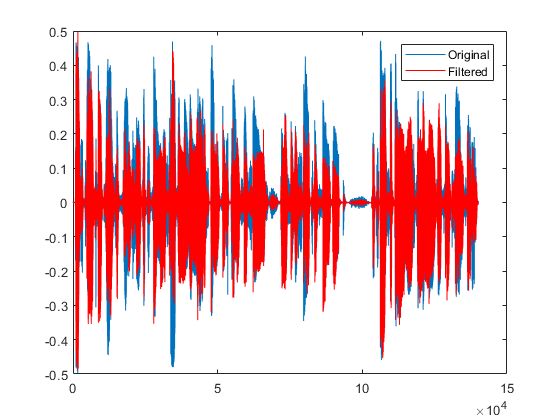

clc;clear
[x,Fs] = audioread('guit1.wav');

X= frame_wind (x, 256, 0.5);
X_size1 = size(X,1);
X_size2 = size(X,2);
x = frame_recon(X,0.5);

Z = zeros(256,1095);
filter_grade = 20;
prediction_param = 10; 

for i = 1:X_size2
    rss = xcorr(X(:,i));
    rxx = rss(X_size1:X_size1 + filter_grade - 1); 
    rss = rss((X_size1 + prediction_param):(X_size1 + prediction_param) + filter_grade - 1);
    Rxx = toeplitz(rxx);
    w = pinv(Rxx,0.0001)*rss;
    z = filter(w,1,X(:,i));
    Z(:,i) = z;
end

z = frame_recon(Z,0.5);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Filtered');

SNR_given_signal = 10 * log10(sum(x.^2) / sum((x-z).^2));
SNR_filtered_signal = 10 * log10(sum(z.^2) / sum((x-z).^2));
disp(['SNR for given signal: ' num2str(SNR_given_signal) ' dB']);

SNR for given signal: -1.8834 dB


disp(['SNR for filtered signal: ' num2str(SNR_filtered_signal) ' dB']);

SNR for filtered signal: -3.6328 dB


**Για πρόβλεψη 15 θέσεων:**

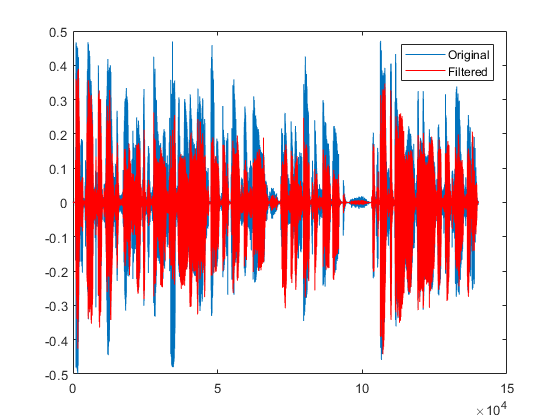

clc;clear
[x,Fs] = audioread('guit1.wav');

X= frame_wind (x, 256, 0.5);
X_size1 = size(X,1);
X_size2 = size(X,2);
x = frame_recon(X,0.5);

Z = zeros(256,1095);
filter_grade = 20;
prediction_param = 15; 

for i = 1:X_size2
    rss = xcorr(X(:,i));
    rxx = rss(X_size1:X_size1+ filter_grade - 1); 
    rss = rss((X_size1 + prediction_param):(X_size1 + prediction_param) + filter_grade - 1);
    Rxx = toeplitz(rxx);
    w = pinv(Rxx,0.0001)*rss;
    z = filter(w,1,X(:,i));
    Z(:,i) = z;
end

z = frame_recon(Z,0.5);

%soundsc(z,Fs)
% Plotting the signals
plot(x);hold on;plot(z,'r');hold off;
legend('Original', 'Filtered');

SNR_given_signal = 10 * log10(sum(x.^2) / sum((x-z).^2));
SNR_filtered_signal = 10 * log10(sum(z.^2) / sum((x-z).^2));
disp(['SNR for given signal: ' num2str(SNR_given_signal) ' dB']);

SNR for given signal: -3.0739 dB


disp(['SNR for filtered signal: ' num2str(SNR_filtered_signal) ' dB']);

SNR for filtered signal: -5.4261 dB


Παρατηρούμε πως όσο αυξάνουμε τις θέσεις που θέλουμε να προβλέψουμε τόσο το σήμα που λαμβάνουμε στην έξοδο αποκλίνει από το αρχικό.

Εάν επιλεχθεί άλλη τάξη φίλτρου π.χ 10 ή 30 κανονικά θα έπρεπε να υπάρχει διαφορά όμως δεν είναι ιδιαίτερα εμφανής από τα plot. Οι τιμές των SNR είναι πολύ μικρές γεγονός που δείχνει πως δεν έχει γίνει καλή πρόβλεψη των επόμενων θέσεων.